# Particle Tracking using Matlab code

## Preamble

Eric Weeks, John Crocker, and David Grier wrote particle tracking code in IDL that has been very useful to the soft matter physics community. However, some researchers are more comfortable programming in Matlab and/or might have access to Matlab for free provided by their institution. Blair (Georgetown) and Dufresne (formerly Yale) provided some particle tracking code, but the code differed a fair amount from the IDL version. This GitHub site and tutorial is an attempt to create Matlab code that is more like the IDL version on Eric Weeks website: 

[https://physics.emory.edu/faculty/weeks/idl/tracking.html](https://physics.emory.edu/faculty/weeks/idl/tracking.html)

That said, the Matlab functions are not identical to the IDL functions -- some 'keywords' were ignored -- but they are very similar. In addition, not all keywords were rigorously tested (some not at all), so please use with caution.  

## "read_vif.m" - Reading in a video file

In our research lab, we use XCAP software by EPIX to grab video files (VIF format). The Matlab function 'read_vif.m' can read these VIF files into Matlab as a 3-dimensional array.  To get it to work correctly, parameters often need to be tweaked. There is a lot of helpful information in the header for read_vif function. 

EXAMPLE:

% Change directoy to the location of the video file ... 
cd('C:\Users\75KAPTOWICZ\OneDrive - West Chester University of PA\Documents\0 WCU - Misc\Matlab\Kevin_Particle_Tracking\VideoFiles')

% Input Parameters:
filename = "NIST 1.vif";  % XCAP video file
pix_w=658;  % pixel width of image
pix_h=494;  % pixel height of image

% Read in video as array 'a' ...
a = read_vif(filename,pix_w,pix_h,bit_10_unpacked='y',byte_offset=72);

Setting byte_spacing to pad frames to interger*512 bytes.
...... byte_spacing = 136 bytes


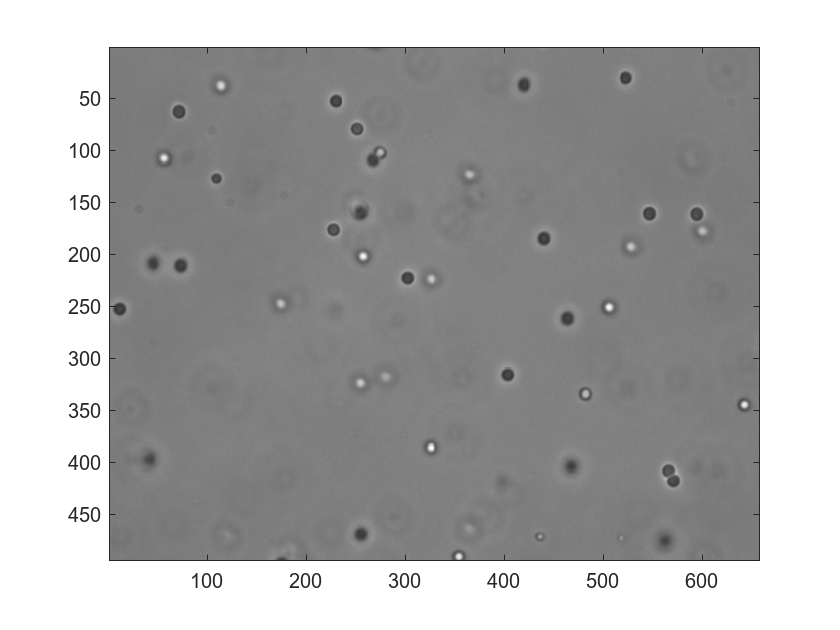

% See header to understand the significance of bit_10_unpacked and
% byte_offset keywords

% *** CHECK ***
% To check if the VIF file was correctly read in, display one image
frame=1; % Can look at other frames as well by changing this number
colormap('gray'); imagesc(a(:,:,frame)); drawnow

NOTE: For your video file, there might be another way to read it into Matlab. As long as you have an 3D array (image stack), you can move onto the next step.  

## "bpass.m" - Spatial filtering the image

The function** bpass** is a spatial bandpass filter which smooths the image and subtracts the background off.  The two numbers are need to perform the spatial filtering.  The first one is almost always '1'. The second number should be something like the diameter of the 'blob's you want to find in pixels.  Try a few values and use the one that gives you nice, sharply peaked circular blobs where your particles were; remember the numbers you used for **bpass**. They will be needed in later steps.  

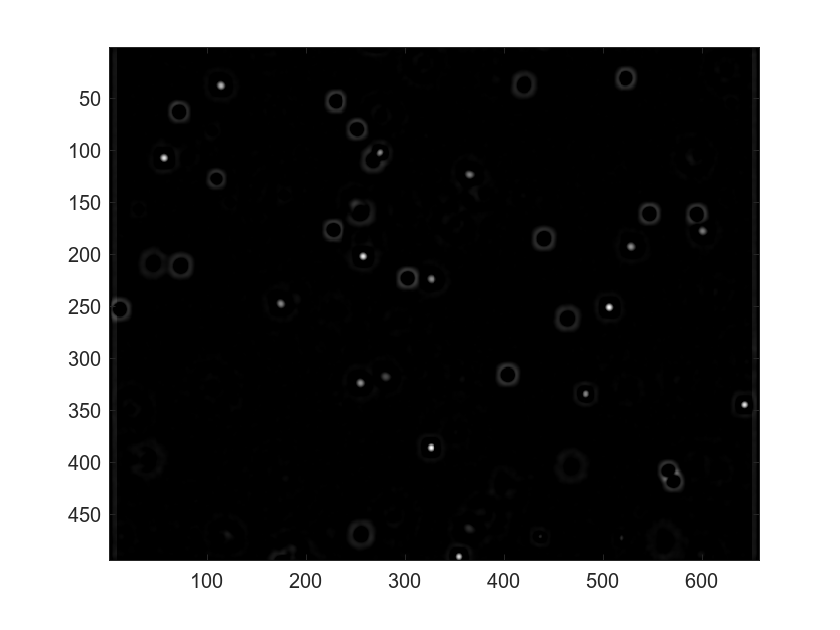

% Input Parameters:
a1 = a(:,:,1);  % The first image of the movie
lnoise=1;       % The high freq cutoff 
lobject=7;      % The low freq cutoff

% The output is a filtered version of the input image ... 
b = bpass(a1,lnoise,lobject); 

% *** CHECK ***
% To check the filtered image, display it ...
colormap('gray'); image(b); drawnow

% It should have nice bright blobs (the particles) on a black background. 

NOTE: lobject should be an odd number.  Vary it and inspect the resultant image. 

## "findfeaures.m" - Identifying the location of the blobs in a single frame

findfeatures.m acts the same way as 'feature' does in IDL (I couldn't call it the same name because of built-in Matlab function).  In the output, each row represents a found feature (a blob).  The columns in each row are: (1) x-position of the blob, (2) y-position of the blob, (3) brightness of the blob, (4) radius of gyration (size), and (5) eccentricity. 


% Input Parameters:
InputImage=b; % Finds features in a single image. The input image is the output image of bpass.
dia = 11;   % Slightly larger than the size of the blobs in bpass  
f = findfeatures(InputImage,dia,min=100,quiet=[]);

FINDFEATURES: 16 features found.


% See header for more information about input parameters.  The 'min' parameter sets a minimum 
% peak brightness needed to identify a blob as a feature.   

% *** CHECK ***
% Look at the first five rows of the array 'f'
disp(f(1:5,:))

   1.0e+03 *

    0.0566    0.1074    6.4705    0.0071    0.0000
    0.1135    0.0375    5.5971    0.0077    0.0000
    0.1744    0.2472    4.4461    0.0080    0.0001
    0.2551    0.3235    4.8175    0.0079    0.0000
    0.2577    0.2018    6.4244    0.0066    0.0000



NOTE: These values might seem small, but they should be scaled by 1.0e+03 or 1000x.  The first and second columns are the x and y positions of the particles. I'll discuss the 3rd, 4th, and 5th columns later. 

## "fover2d.m" - Checking the found features

The function fover2D.m is useful to check the blobs identified by findfeatures. It creates an image in which the found blobs are circled.  See header for more information about the difference input parameters. 

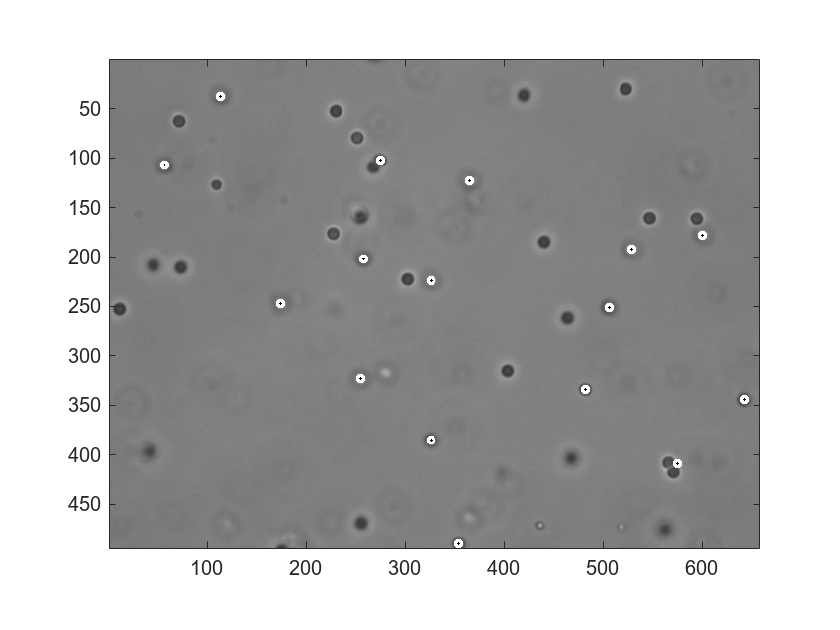

% Display the image (a1) and the found features in that image (f).  
fo=fover2d(a1, f); drawnow

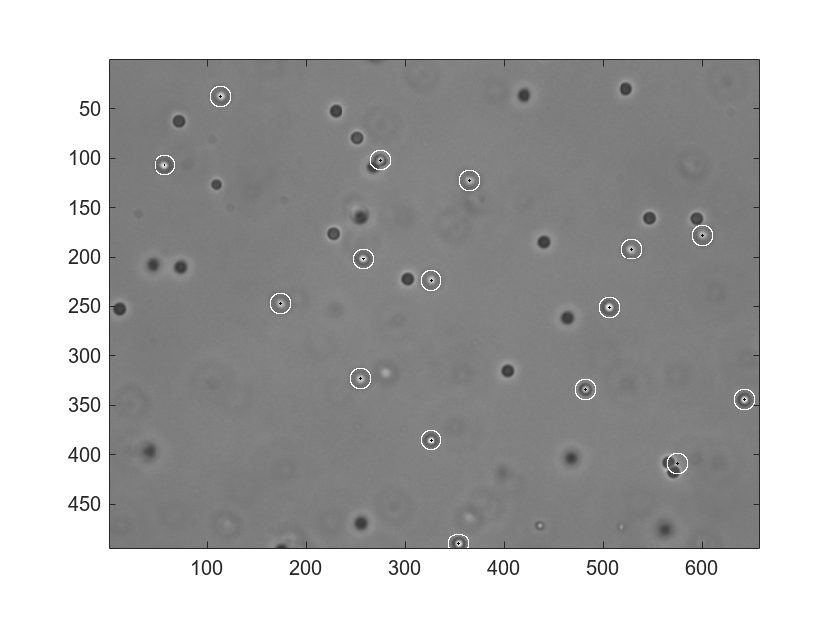


% Using some keywords can make it easier to see ...
fo=fover2d(a1, f, circle='y', radius=11); drawnow


% See header for more information about keywords

NOTE: If the quality of the analysis is poor (particles are porrly identified), adjust parameters as needed until the particles are accurately identified. 

## "epretrack.m" - Characterize blobs in all frames

Once you know the parameters needed for bpass and findfeature, you are ready to analyze all the frames in the video and identify the particles in all frames.  The function epretrack will do this analysis.  It uses the functions bpass and findfeature on each frame and stores all the results as a single array. 

pt_all=epretrack(a,bplo=1,bphi=9,dia=11,min=100);

Defaults: sep-unset mass-unset
starting epretrack...
processing frame 50 out of 1000....
processing frame 100 out of 1000....
processing frame 150 out of 1000....
processing frame 200 out of 1000....
processing frame 250 out of 1000....
processing frame 300 out of 1000....
processing frame 350 out of 1000....
processing frame 400 out of 1000....
processing frame 450 out of 1000....
processing frame 500 out of 1000....
processing frame 550 out of 1000....
processing frame 600 out of 1000....
processing frame 650 out of 1000....
processing frame 700 out of 1000....
processing frame 750 out of 1000....
processing frame 800 out of 1000....
processing frame 850 out of 1000....
processing frame 900 out of 1000....
processing frame 950 out of 1000....
processing frame 1000 out of 1000....


'a' is the video array. 'bplo' and 'bphi' are inputs into bpass. 'dia' is the input into findfeatures. 'min' is an optional parameter for the function findfeatures. Read about it in the findfeatures header. 

% *** CHECK ***
% Look at the size of pt to see how many particles were found ... 
disp(size(pt_all))

       13883           6



% The first number is the number of particles found (also the number of rows). 
% The second number is the number of columns.  5 of them are the same as findfeatures. 
% The 6th column is the frame number in which the particle was found. 

## Evaluate the quality of the pre-track array (IMPORTANT)

This is a critical step in the process.  Just because a "particle" was found, doesn't mean it is an actual particle. There are many possible artifacts that can be misidentified as particles.  You can use properties of the blobs (i.e. brightness, size, and eccentricity) to remove artifacts that were misidentified as particles.  

First, let's take a look at the locations found by plotting them all ... 

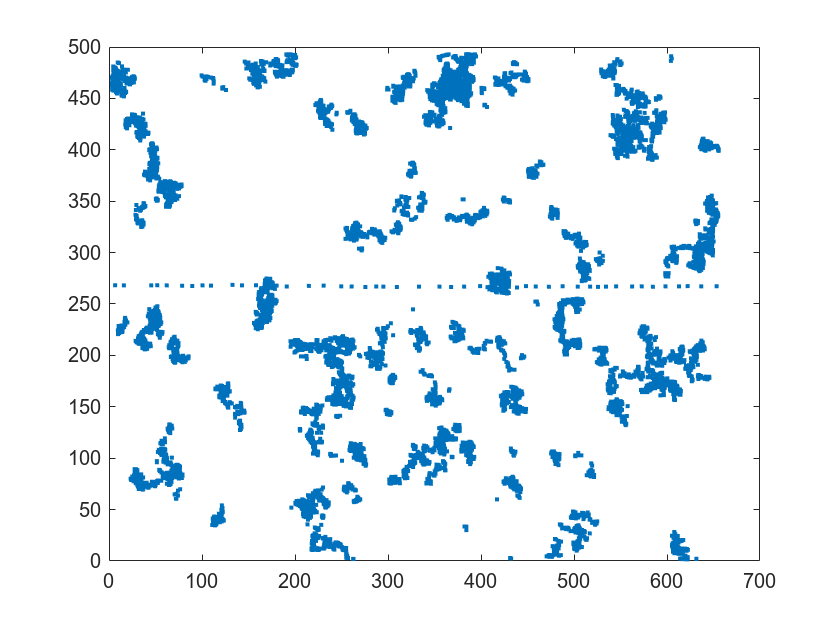

plot(pt_all(:,1),pt_all(:,2),'.'); drawnow

Looks okay, but has a strange line across the middle.  This turns out to be some noise in frame 382 that suddenly appeared. Luckily we should be able to get ride of it by filtering. 

### Histograms of individual particle properties

Let's looks at the mass, brightness, and eccentricity ... 

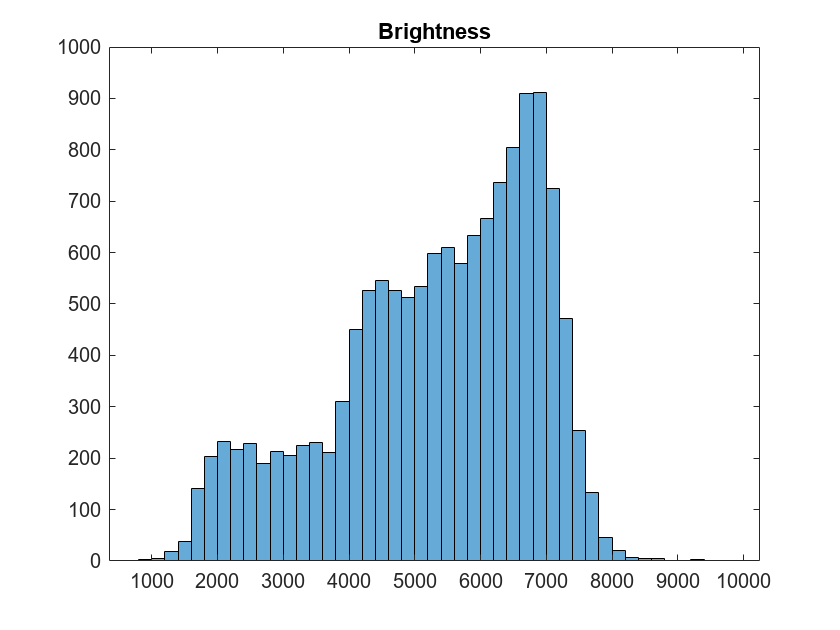

histogram(pt_all(:,3))
title('Brightness'); drawnow

At first glance ... the histogram of the brightness looks reasonable. 

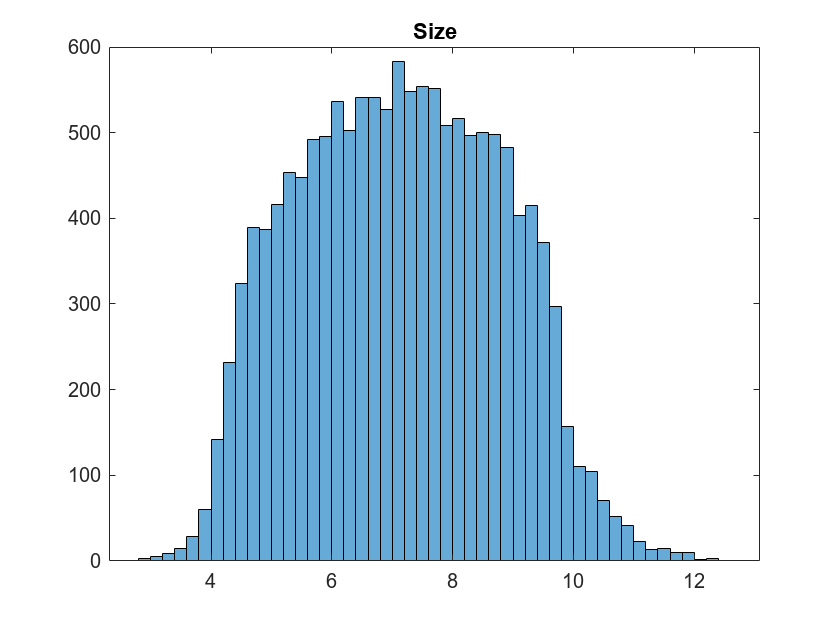

histogram(pt_all(:,4))
title('Size'); drawnow

Histogram of the size looks very good. The distribution is centered around 7, which is about the diameter of the blobs from bpass.  

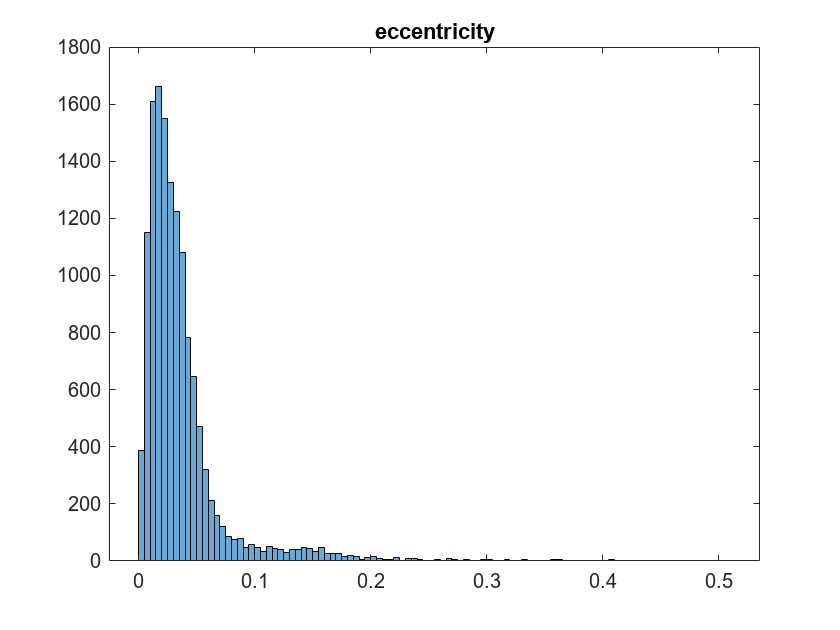

histogram(pt_all(:,5)); 
title('eccentricity'); drawnow

Eccentricity varies from 0 to 1, but the blobs should be circular, so the eccentrity values should be pretty close to 0. The features with large eccentricity value (e.g. > 0.1) might be unwanted artifacts. 

### Plots of particle properties

It can be insightful to look at multiple propeties at the same time.  Let's look at brightness and eccentricity: 

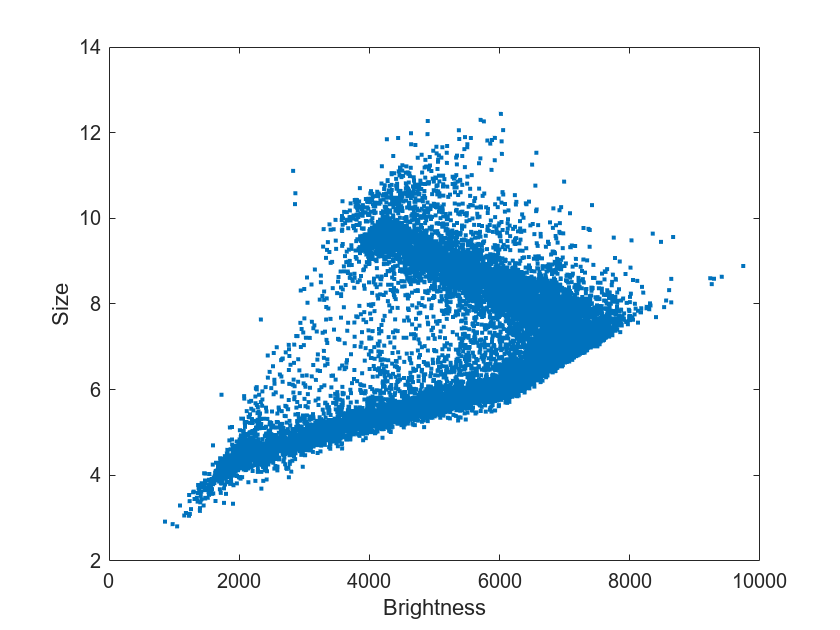

plot(pt_all(:,3),pt_all(:,4),'.'); drawnow 
xlabel('Brightness')
ylabel('Size')

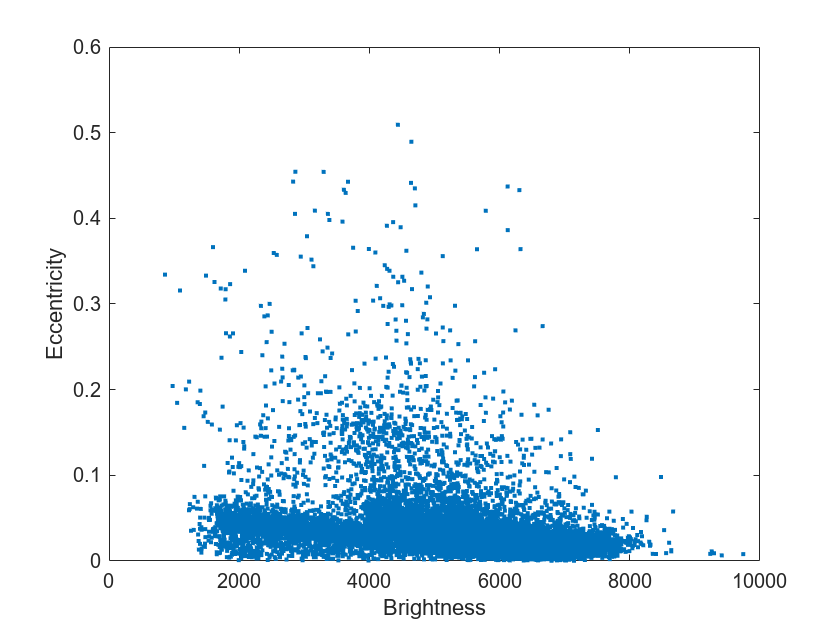


plot(pt_all(:,3),pt_all(:,5),'.'); drawnow 
xlabel('Brightness')
ylabel('Eccentricity')

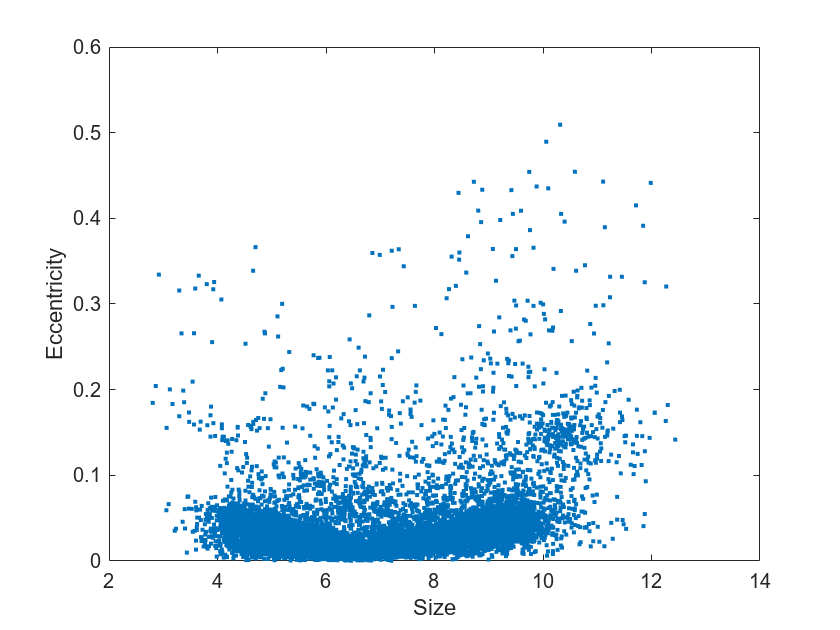


plot(pt_all(:,4),pt_all(:,5),'.'); drawnow 
xlabel('Size')
ylabel('Eccentricity')

### Movie of filtered particles 

If I think the particles with a eccentricity greater than 0.1 are artifacts, I should check if that is true.  Using fover2d and the find function, I can make a movie of those particles.  To minimze processing time, I'm just going to create a movie of the first 100 frames.  

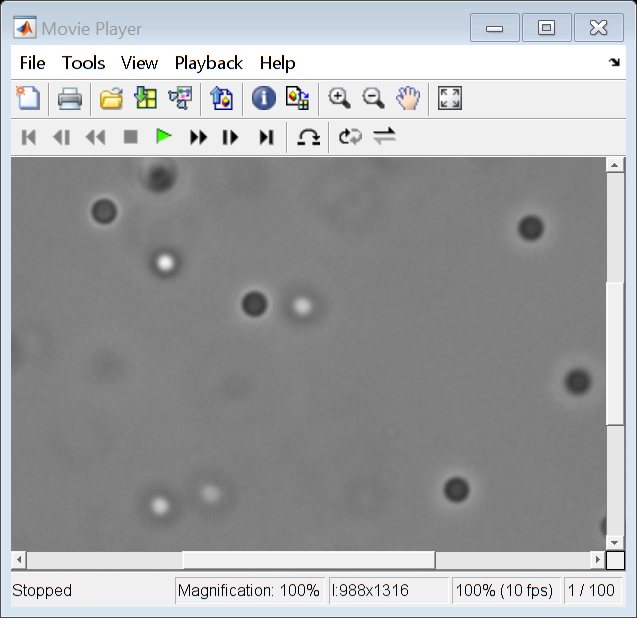

w=find(pt_all(:,5) > 0.1); % index of particles with an eccentricity > 0.1
fo=fover2d(a(:,:,1:100),pt_all(w,:),circle='y',radius=11,big='y'); % Make a movie of those particles 

Of course, this approach can be used to create movies of particles with a specific range of values of brightness and size. 

### Filtering the pretrack array

After playing around with tthe values and looking at different movies, it seems like eccentricity <0.06 is a good threshold to remove artifacts.  Create a new array called pt with just these particles. 

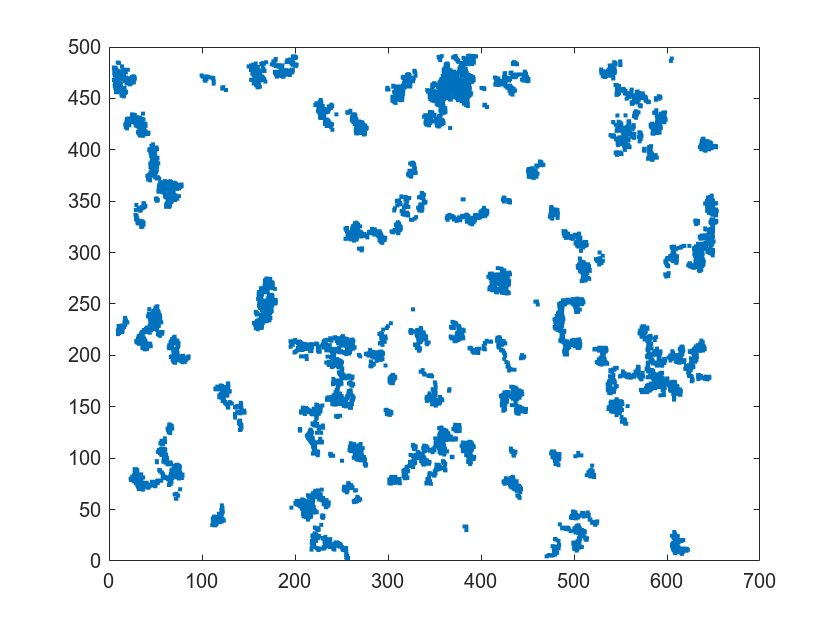

w=find(pt_all(:,5) < 0.06); % index of particles with an eccentricity > 0.1
pt=pt_all(w,:); % New array of 'good' particles
% *** CHECK ***
% Look at the size of pt to see how many particles were found ... 
plot(pt(:,1),pt(:,2),'.'); drawnow

## Checking for pixel bias (IMPORTANT)

Incorrect input parameters for bpass and feature can diminish the precision of the found locations of the particles.  This is called pixel bias and can negate subpixel resolution.  The check if pixel bias is an issue,  make of plot of the fractional part of the particle's x and y locations. This can be done using the mod function. For example, mod(1.345,1) is 0.345 and mod(1010.729,1) is 0.729. A histogram of these values for the x and y positions should be fairly flat (uniform), as shown. 

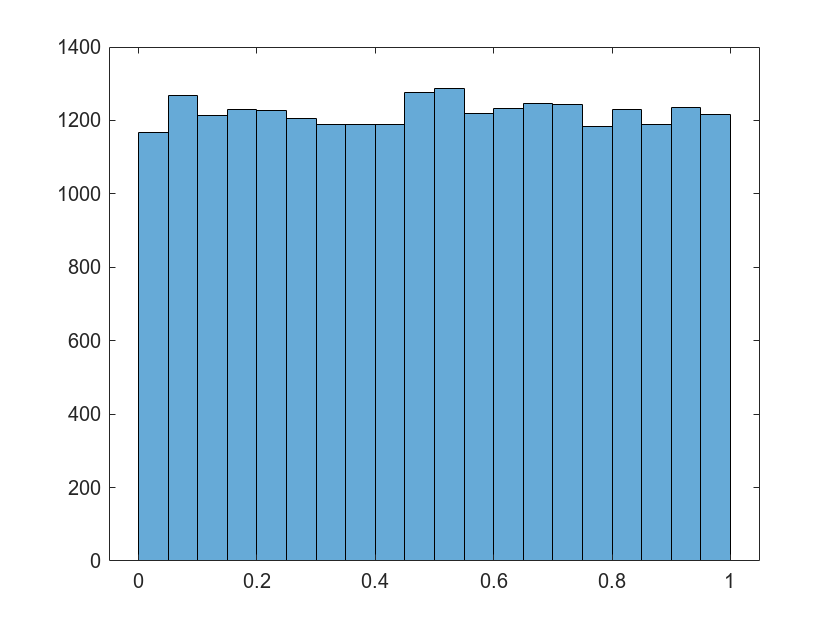

histogram(mod(pt(:,1:2),1),20); drawnow

## "track.m" - Linking particle trajectories. 

At this point, the pretrack array has the locations of the particles (columns 1 and 2) and the frame number (column 6). The next step is to link a particle in one frame to the same particle in the next frame. The function 'track.m' accomplishes this task and add's a new column of particle ID.  

t=track(pt,6,dim=2,memory=3,goodenough=10);

Frame 50 of 1000 done. Current frame has 12 particles. 
Frame 100 of 1000 done. Current frame has 12 particles. 
Frame 150 of 1000 done. Current frame has 6 particles. 
Frame 200 of 1000 done. Current frame has 12 particles. 
Frame 250 of 1000 done. Current frame has 7 particles. 
Frame 300 of 1000 done. Current frame has 11 particles. 
Frame 350 of 1000 done. Current frame has 12 particles. 
Frame 400 of 1000 done. Current frame has 11 particles. 
Frame 450 of 1000 done. Current frame has 13 particles. 
Frame 500 of 1000 done. Current frame has 17 particles. 
Frame 550 of 1000 done. Current frame has 13 particles. 
Frame 600 of 1000 done. Current frame has 14 particles. 
Frame 650 of 1000 done. Current frame has 12 particles. 
Frame 700 of 1000 done. Current frame has 15 particles. 
Frame 750 of 1000 done. Current frame has 5 particles. 
Frame 800 of 1000 done. Current frame has 12 particles. 
Frame 850 of 1000 done. Current frame has 13 particles. 
Frame 900 of 1000 done. Current fra

The first input is the pretrack array.  The second input is the maximum distance a particle can move (in pixels) from one frame to the next. See header of the track function file for inofrmation on the optional input parameters like memory and goodenough.  

## "plottr.m" - Plotting particle trajectories. 

Next, it is helpful to take a look at the output of track. the function 'plottr.m' allows you to look at all the found tracks, plot individual tracks by ID #, or plot only tracks larger or equal to a certain length using 'goodenough.'

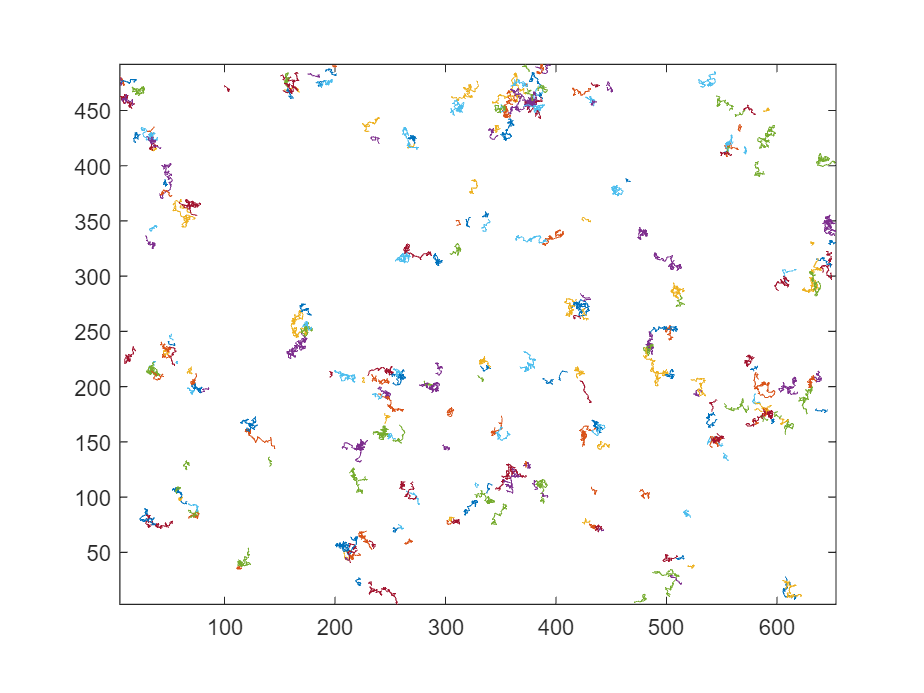

plottr(t);

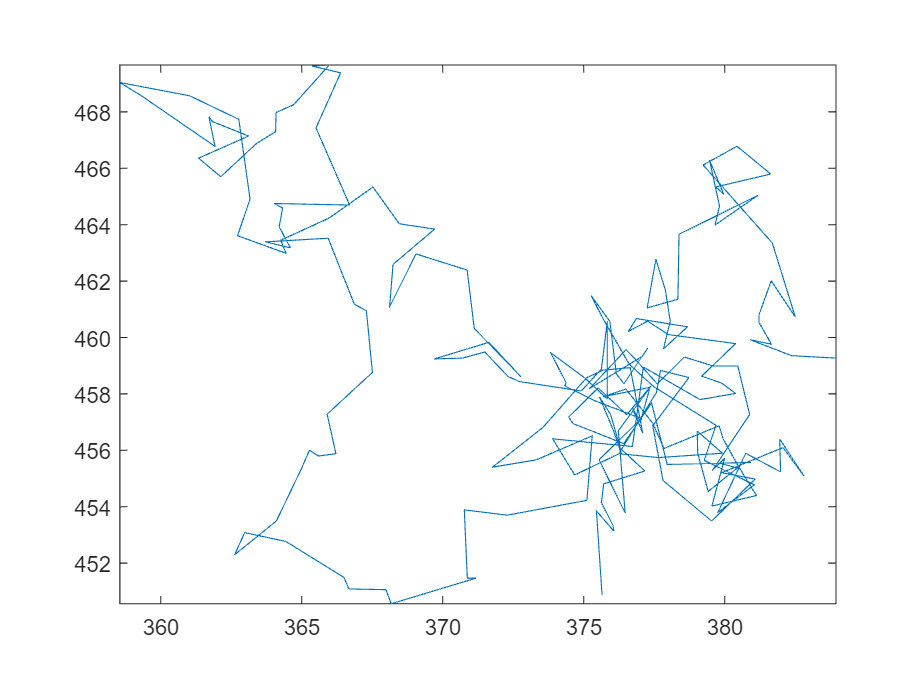

plottr(t, ID=130);

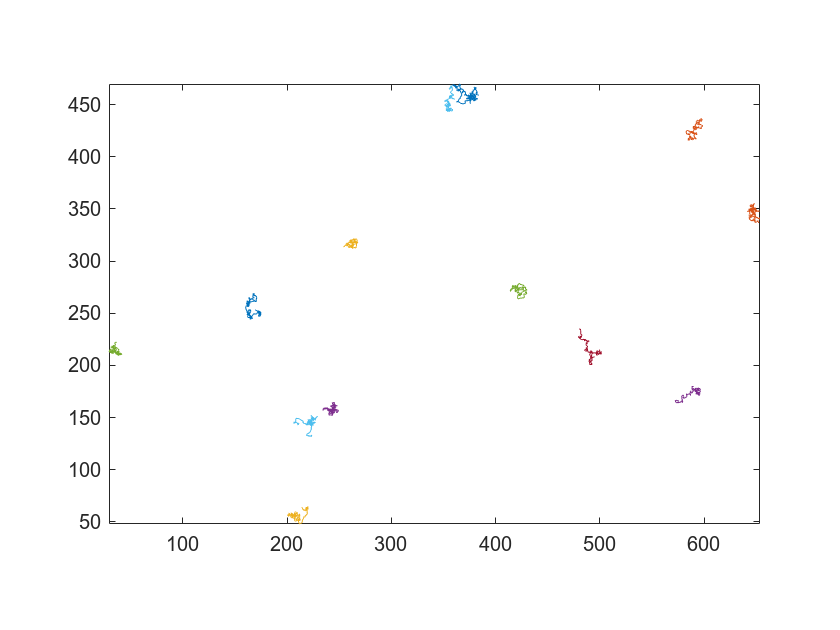

plottr(t, goodenough=100);

## "seeall.m" - Exploring the found tracks

The seeall.m function is a helpful tool to explore the found particle tracks. It shows the properties of a single track. By selecting the figure (or command line if livescript) and hitting <enter> you can see all of your trajectories, longest duration first.  

This function is better used as a command in the command line rather than in a livescript. 

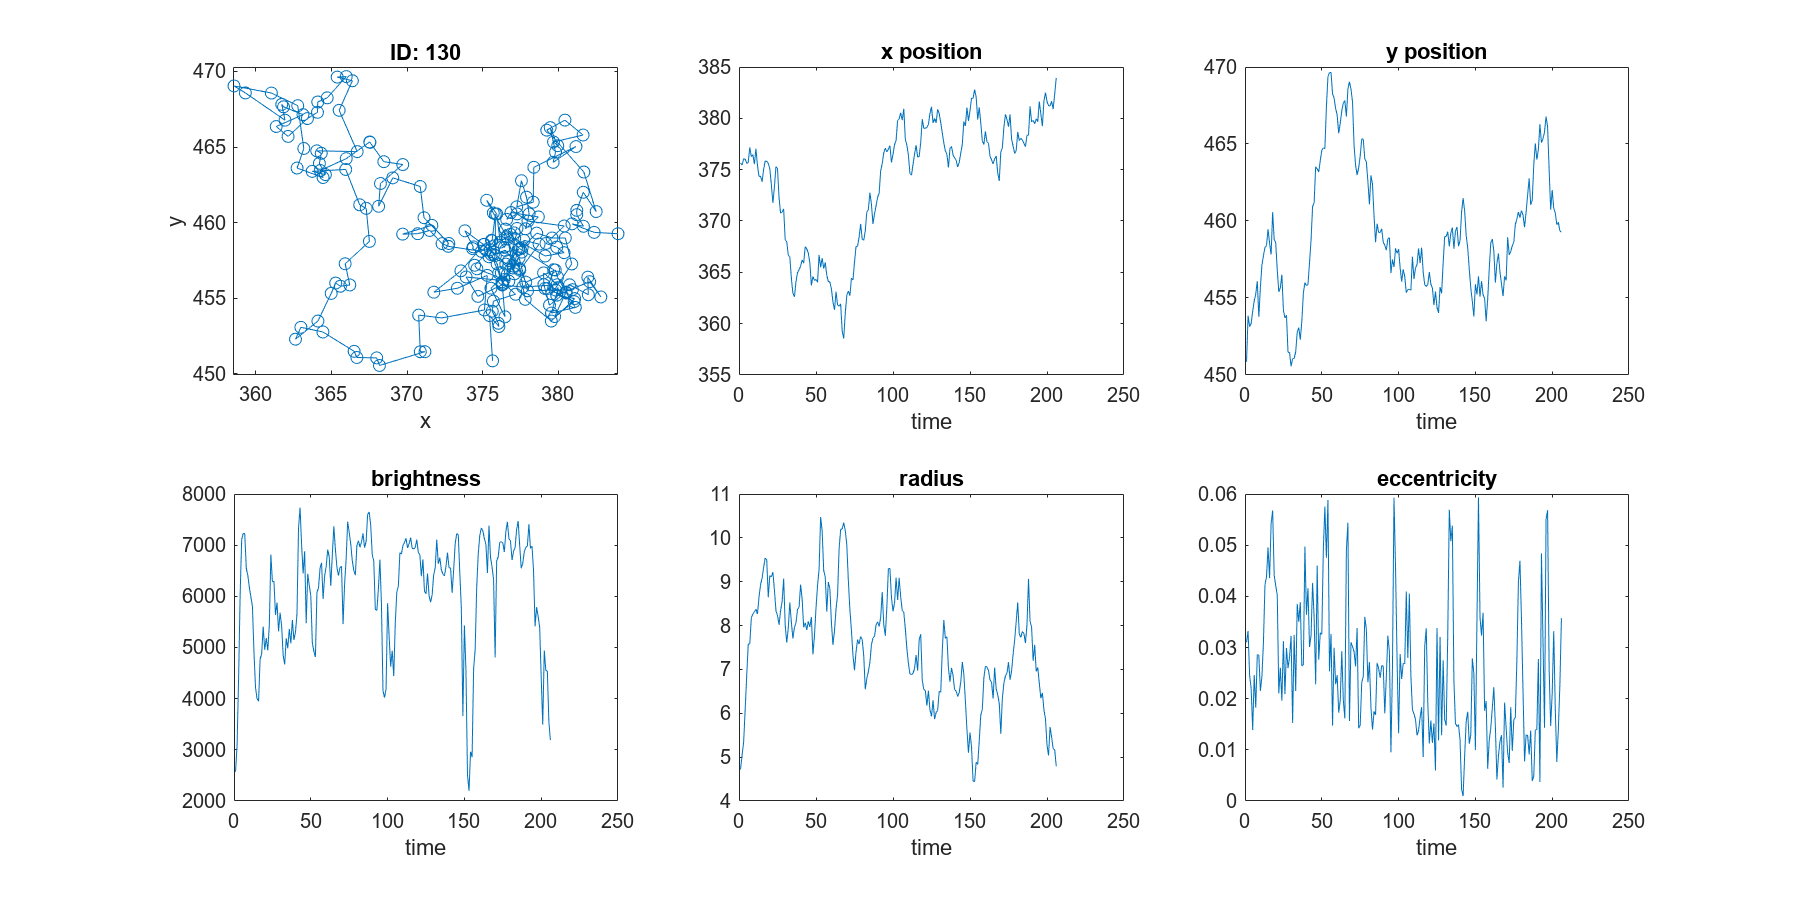

Next track? Enter to continue. Q to quit.


seeall(t)

close all

## 'getdx.m' and 'mkpdf.m' - Checking 'track.m' input parameter 

In the track.m finction, the second input variable is the maximum distance a particle can move (in pixels) from one frame to the next. To check this value, use mkpdf.m which utilizes the function 'getdx.m.' The function getdx calculates the change in x and change in y between a set number of frames. The number of frames to use is the second input value in either getdx or mkpdf. Reader headers for more information. 

The code below plots two histograms. The first histogram shows all the values of dx and dy for a change in time of 1 frame. The red line is a gaussian fit to the distribution. 

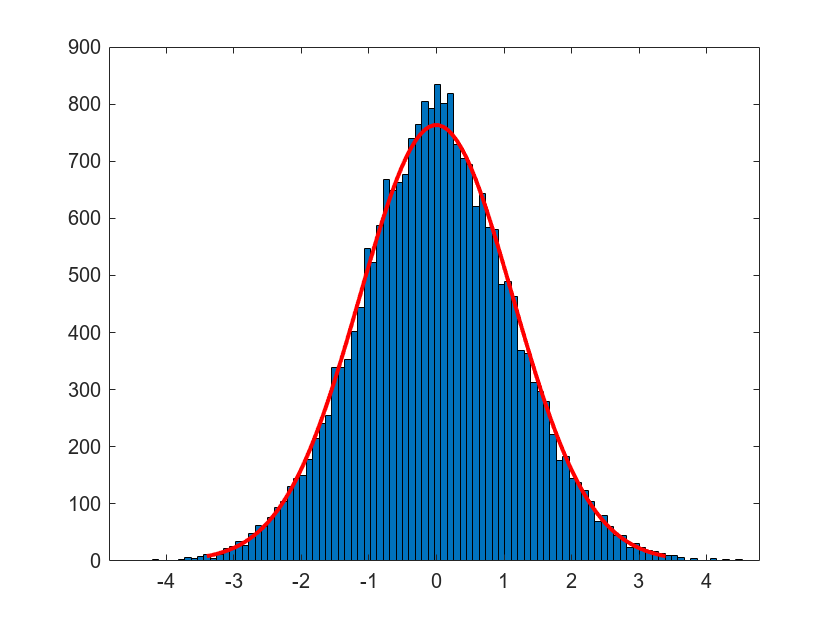

dx=mkpdf(t,1); 
histfit(dx(:),100,'normal'); drawnow

We care about what is happening at the tails of the distribution.  It is easier to see this with a log scale for the vertical axis.  Seems like there are no dx or dy values larger than 5 thus setting the max displacement to 6 was a resonable value.  The value 5 would have also worked. 

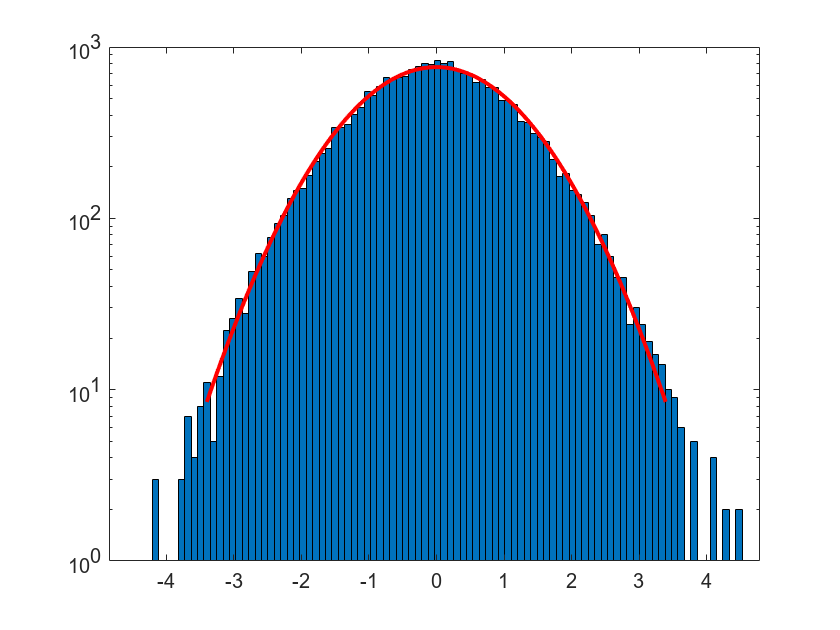

dx=mkpdf(t,1); 
histfit(dx(:),100,'normal'); set(gca,'YScale','log'); drawnow

Rather than looking at a time difference of one frame, we can also look at a time difference of 10 frames. The distribution gets wider (makes sense) but still has a Gaussian shape. 

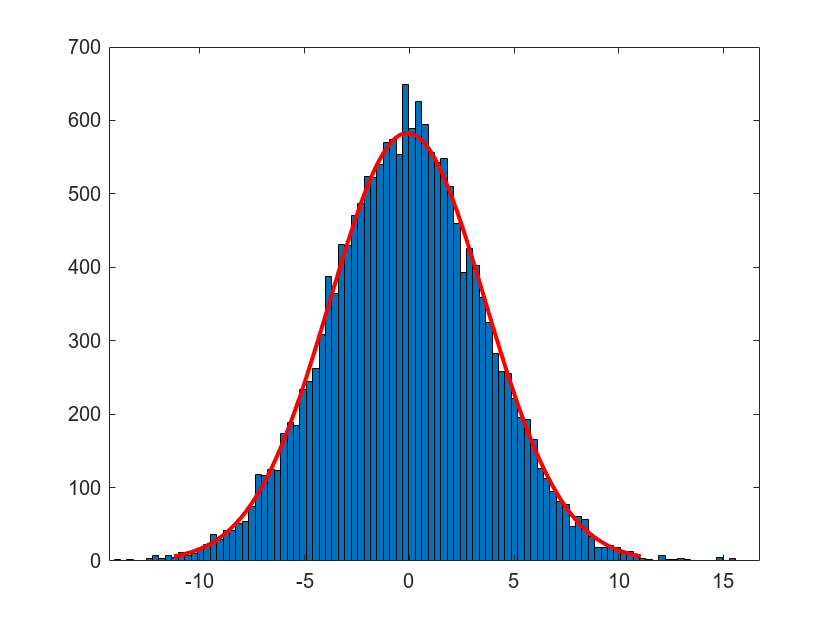

dx=mkpdf(t,10); 
histfit(dx(:),100,'normal'); drawnow

## 'msd.m' - Calculating the mean squared displacement

The mean squared displacement (msd) is a useful way to meaure the diffusion of particles.  For normal diffusion, the msd increases linearly with delay time.  There is a lot more information (an input options) for the msd function discussed in the header or Eric Weeks website. 

dt equals: 1
dt equals: 2
dt equals: 3
dt equals: 4
dt equals: 5
dt equals: 6
dt equals: 7
dt equals: 8
dt equals: 9
dt equals: 11
dt equals: 12
dt equals: 14
dt equals: 16


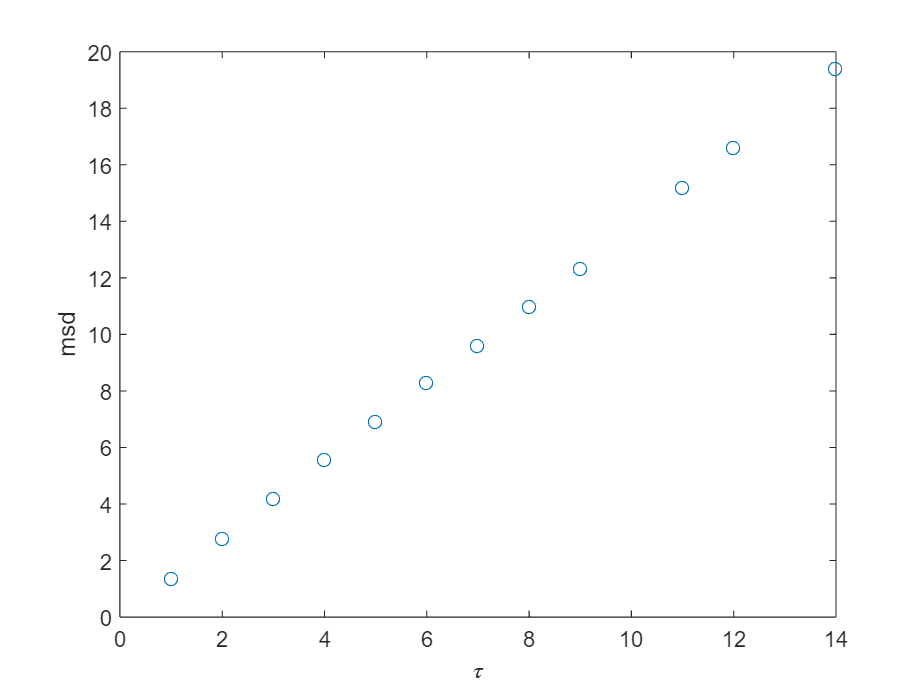

m=msd(t);

## 'linearfit.m' - Linear fit parameters with uncertainty

The function 'linearfit.m' fits a line to data points and calculates the uncertainty of the slope and intercept of the line. It uses expressions from Chapter 8 in John Taylor's Error Analysis book. 

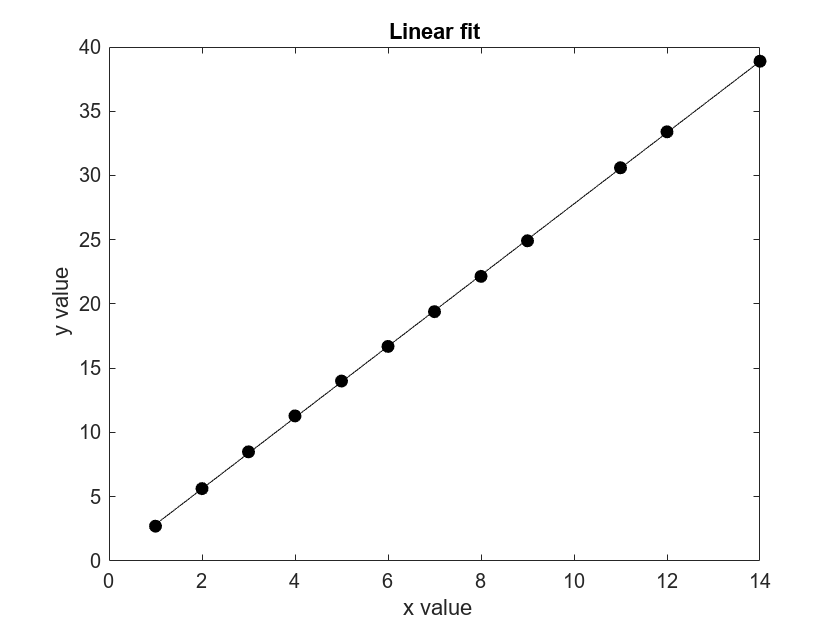

*** Linear fit parameters ***

Slope | uncertainty
    2.7720    0.0067

Intercept | uncertainty
    0.0745    0.0527



res=linearfit(m(:,1),m(:,6));

## Summary

You do not need to use all these functions every time you do an analysis of a video file.  Often, if you know your input parameters and have read in your video as an array, you can just run epretrack and track ... two lines of code ... to analyze your data and pull out particle tracks. What you do with those tracks will depend on your research question.  

Hopefully that wasn't too confusing. Enjoy.